# Práctica 4 - SLAM con filtro de partículas (FastSLAM) y planeamiento de trayectorias - Rodríguez, Maximiliano

## 1: Implementación de algoritmo FastSLAM

Se pidió implementar el paso de corrección, asumiendo que la matriz de ruido de medición es igual a $Q_{t\;} =\left\lbrack \begin{array}{cc}
0\ldotp 1 & 0\\
0 & 0\ldotp 1
\end{array}\right\rbrack$.


function particles = correction_step(particles, z)

% Weight the particles according to the current map of the particle
% and the landmark observations z.
% z: struct array containing the landmark observations.
% Each observation z(j) has an id z(j).id, a range z(j).range, and a bearing z(j).bearing
% The vector observedLandmarks indicates which landmarks have been observed
% at some point by the robot.

% Number of particles
numParticles = length(particles);

% Number of measurements in this time step
m = size(z, 2);

% TODO: Construct the sensor noise matrix Q_t (2 x 2)
Q_t = [0.1 0; 
        0 0.1];


% process each particle
for i = 1:numParticles
  robot = particles(i).pose;
  % process each measurement
  for j = 1:m
    % Get the id of the landmark corresponding to the j-th observation
    % particles(i).landmarks(l) is the EKF for this landmark
    l = z(j).id;

    % The (2x2) EKF of the landmark is given by
    % its mean particles(i).landmarks(l).mu
    % and by its covariance particles(i).landmarks(l).sigma

    % If the landmark is observed for the first time:
    if (particles(i).landmarks(l).observed == false)

      % TODO: Initialize its position based on the measurement and the current robot pose:
      theta = robot(3);
      r = z(j).range;
      b = z(j).bearing;
      landmark_x = robot(1) + r * cos(theta + b);
      landmark_y = robot(2) + r * sin(theta + b);
      particles(i).landmarks(l).mu = [landmark_x; landmark_y];

      % get the Jacobian with respect to the landmark position
      [h, H] = measurement_model(particles(i), z(j));

      % TODO: initialize the covariance for this landmark
      particles(i).landmarks(l).sigma = inv(H) * Q_t * inv(H)';

      % Indicate that this landmark has been observed
      particles(i).landmarks(l).observed = true;

    else

      % get the expected measurement
      [expectedZ, H] = measurement_model(particles(i), z(j));

      % TODO: compute the measurement covariance
      Q = H * particles(i).landmarks(l).sigma * H' + Q_t;

      % TODO: calculate the Kalman gain
      K = particles(i).landmarks(l).sigma * H' * inv(Q);

      % TODO: compute the error between the z and expectedZ (remember to normalize the angle using the function normalize_angle())
      diffZ = [z(j).range - expectedZ(1);
         normalize_angle(z(j).bearing - expectedZ(2))];

      % TODO: update the mean and covariance of the EKF for this landmark
      particles(i).landmarks(l).mu = particles(i).landmarks(l).mu + K*(diffZ);
      particles(i).landmarks(l).sigma = (eye(2) - K*H) * particles(i).landmarks(l).sigma;

      % TODO: compute the likelihood of this observation, multiply with the former weight
      %       to account for observing several features in one time step
      weight = exp(-0.5 * diffZ' * inv(Q) * diffZ) / sqrt((2*pi)^2 * det(Q));
      particles(i).weight = particles(i).weight * weight;

    end

  end % measurement loop
end % particle loop

end


## 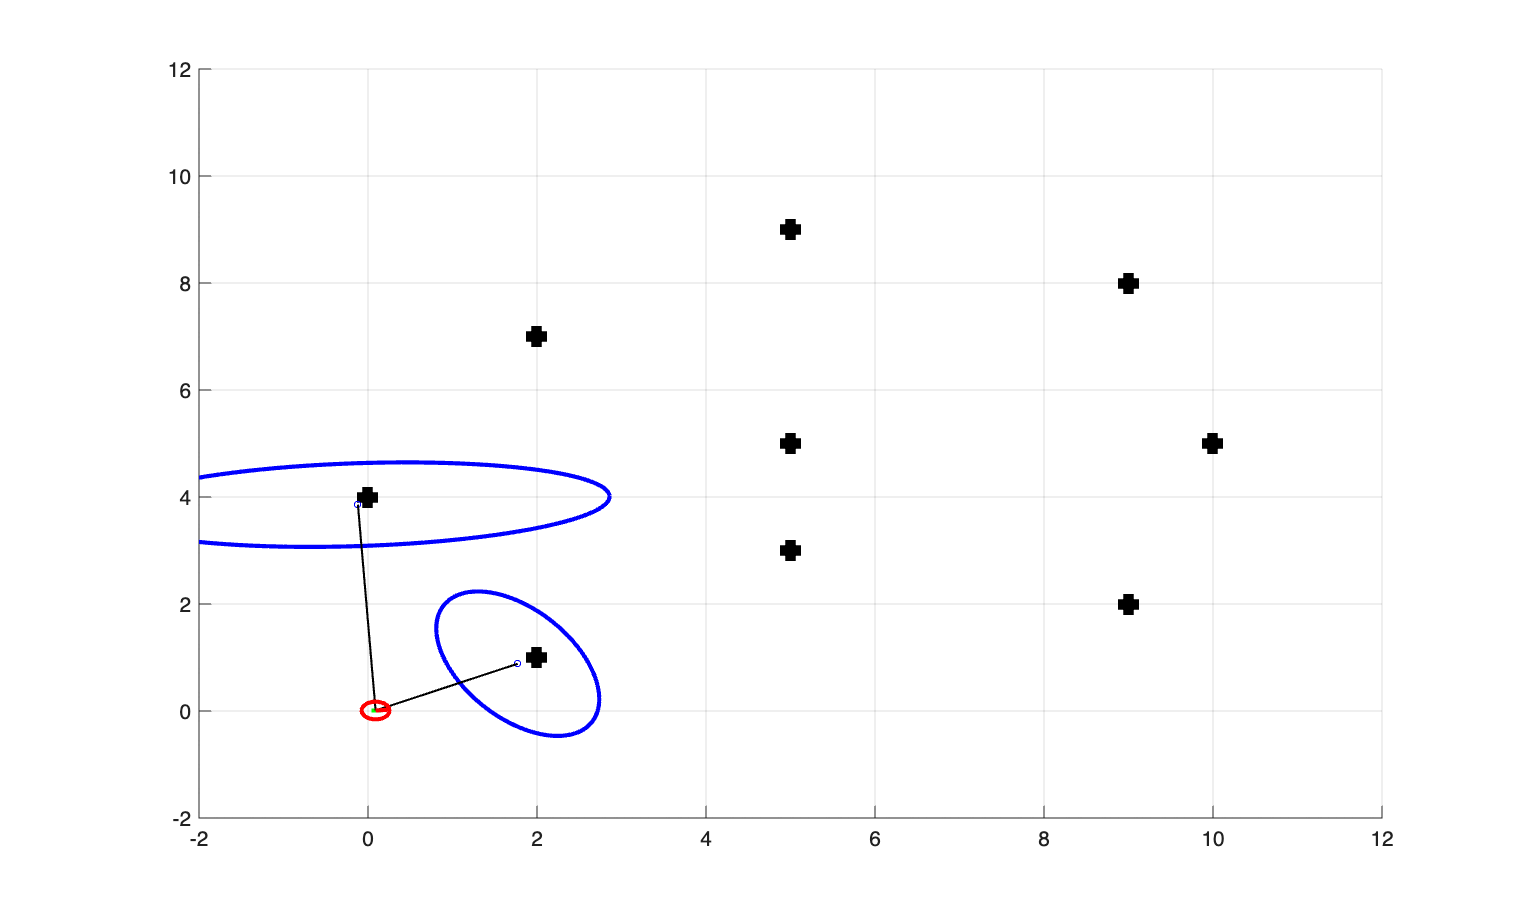

## **2: Planeamiento de trayectorias**

### **2.1: Algoritmo de Dijkstra**

El algoritmo de Dijkstra se usa para calcular caminos de costo mínimo dentro de un grafo. Durante la búsqueda, siempre se busca el nodo del grafo con el menor costo desde el punto de inicio y se agregan los nodos vecinos al grafo de búsqueda.

### **2.2: Función de vecinos**

Se implementó la función que dada una celda devuelve los 8 vecinos de la misma, teniendo en cuenta los límites del mapa.

function n = neighbors(cell, map_dimensions)

  n = [];

  pos_x = cell(2);
  pos_y = cell(1);
  size_x = map_dimensions(2);
  size_y = map_dimensions(1);
  
  %%% YOUR CODE FOR CALCULATING THE NEIGHBORS OF A CELL GOES HERE
  % Return nx2 vector with the cell coordinates of the neighbors. 
  % Because planning_framework.m defines the cell positions as pos = [cell_y, cell_x],
  % make sure to return the neighbors as [n1_y, n1_x; n2_y, n2_x; ... ]

  % Movimientos en los 8 sentidos: N, S, E, O, NE, NO, SE, SO
  directions = [ -1,  0;  % Norte
                  1,  0;  % Sur
                  0, -1;  % Oeste
                  0,  1;  % Este
                 -1, -1;  % Noroeste
                 -1,  1;  % Noreste
                  1, -1;  % Suroeste
                  1,  1]; % Sureste

  for i = 1:8
      new_y = pos_y + directions(i,1);
      new_x = pos_x + directions(i,2);

      % Verificamos que el nuevo vecino esté dentro del mapa
      if new_y >= 1 && new_y <= size_y && new_x >= 1 && new_x <= size_x
          n = [n; new_y, new_x];
      end
  end
end


### **2.3: Función de costo**

Se implementó una función para los costos de un arco entre nodos que permita planear caminos de mínima longitud y libre de colisiones. Se consideró la celda como un obstáculo si su probabilidad de ocupación supera cierto umbral. En este caso el umbral es 0.5 el cual representa que no tenemos información sobre esas celdas.

function cost = edge_cost(parent, child, map)

  threshold = 0.5;

  % Chequear si la celda hija está ocupada
  if map(child(1), child(2)) < threshold
      % Calcular distancia euclidiana penalizando probabilidades mayores de
      % estar ocupadas
  cost = sqrt((child(1) - parent(1))^2 + (child(2) - parent(2))^2);
  else
      % Penalizar celdas ocupadas
      cost = 1e6;
  end
end

El mapa obtenido junto con la ruta al objetivo fue el siguiente:

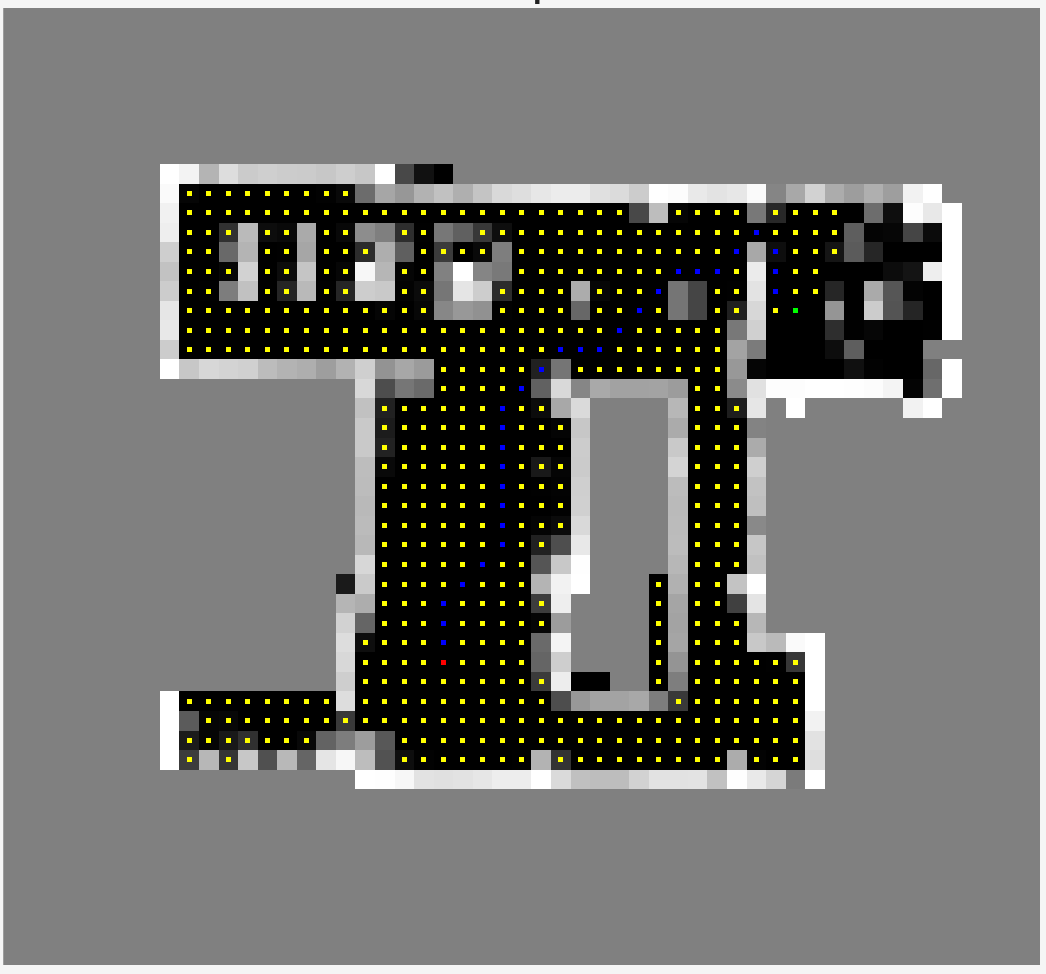

`planning_framework`

`done`

`path cost: `

`   35.7990`

`path length: `

`   35.7990`

`number of nodes visited: `

`   542`

Luego, se incluyó información de ocupación en la función de costo que permita que el algoritmo elija celdas con baja probabilidad de ocupación sobre celdas con mayor probabilidad de ocupación.

function cost = edge_cost(parent, child, map)

  threshold = 0.8;

  % Chequear si la celda hija está ocupada
  if map(child(1), child(2)) < threshold
      % Calcular distancia euclidiana penalizando probabilidades mayores de
      % estar ocupadas
  cost = sqrt((child(1) - parent(1))^2 + (child(2) - parent(2))^2) + 100 * map(child(1), child(2));
  else
      % Penalizar celdas ocupadas
      cost = 1e6;
  end
end


## 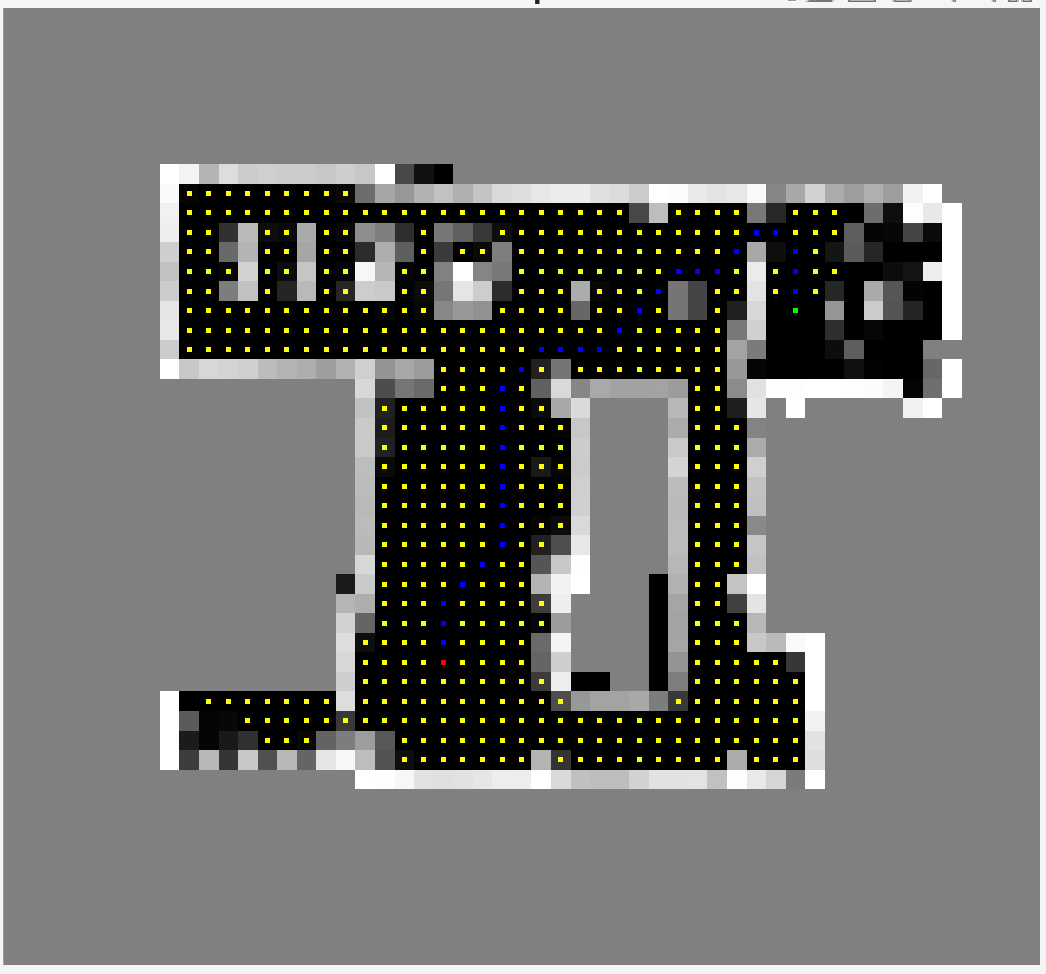

`planning_framework`

`done`

`path cost: `

`   37.0846`

`path length: `

`   36.9706`

`number of nodes visited: `

`   515`

### 2.4: Algoritmo A*

El algoritmo A* utiliza una heurística para realizar una búsqueda informada que resulta ser más eficiente que el algoritmo de Dijkstra, la cual tiene las siguientes propiedades para asegurar que A* es óptimo.

function heur = heuristic(cell, goal)
% g(n) = costo del estado inicial hasta n.
% h(n) = costo estimado desde n hasta el objetivo.
% f(n) = g(n) + h(n), costo estimado de la solución de
% menor costo a través de n.

% Sea h*(n) el costo del camino óptimo desde n hasta el
% objetivo.
% h es admisible si se cumple para todo n que:
% h(n) ≤ h*(n)

% Para A*, se necesita que h sea admisible
% (la distancia recta es admisible en el espacio euclídeo).

  dx = cell(2) - goal(2);
  dy = cell(1) - goal(1);

  heur = sqrt(dx^2 + dy^2);
end

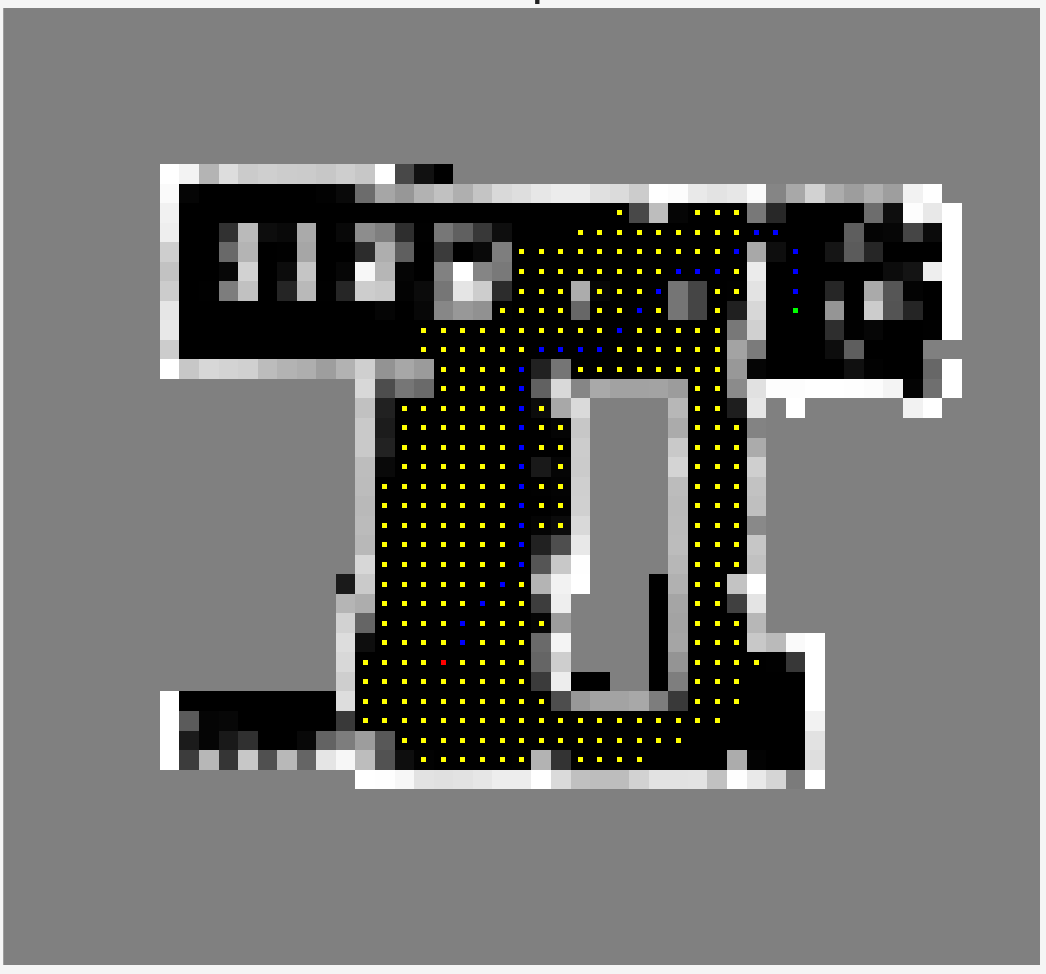

`planning_framework`

`done`

`path cost: `

`   37.0846`

`path length: `

`   36.9706`

`number of nodes visited: `

`   344`

Luego, se definió la nueva heurística $h_2 =k*h$ con $k=\left\lbrace 1,2,5,10\right\rbrace$. Esto hace que pese más la dirección hacia el objetivo. Para el caso $k_1 \;$tenemos el mismo gráfico que el anterior. Para $k_2$ tenemos lo siguiente:

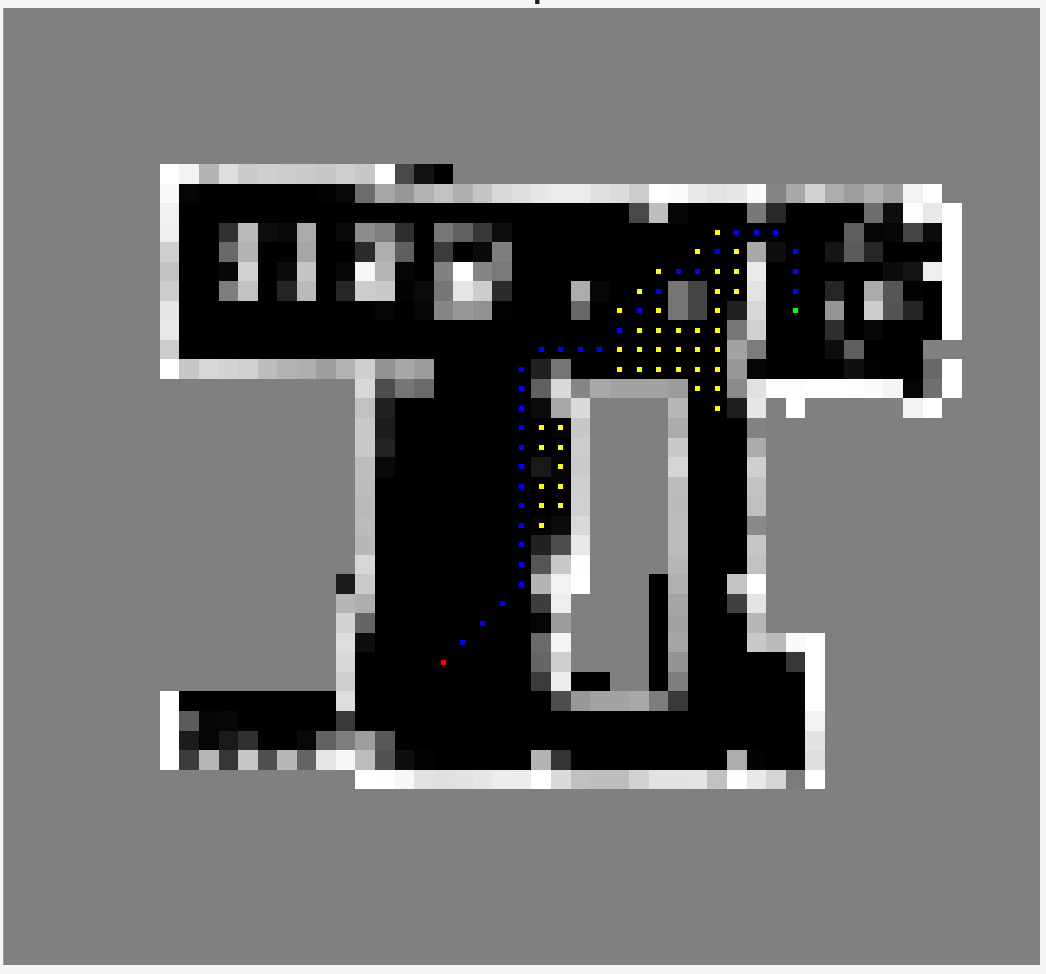

`planning_framework`

`done`

`path cost: `

`   37.6704`

`path length: `

`   36.9706`

`number of nodes visited: `

`    75`

Para k = 5 se observó que se recorren menos nodos pero el costo del viaje aumenta:

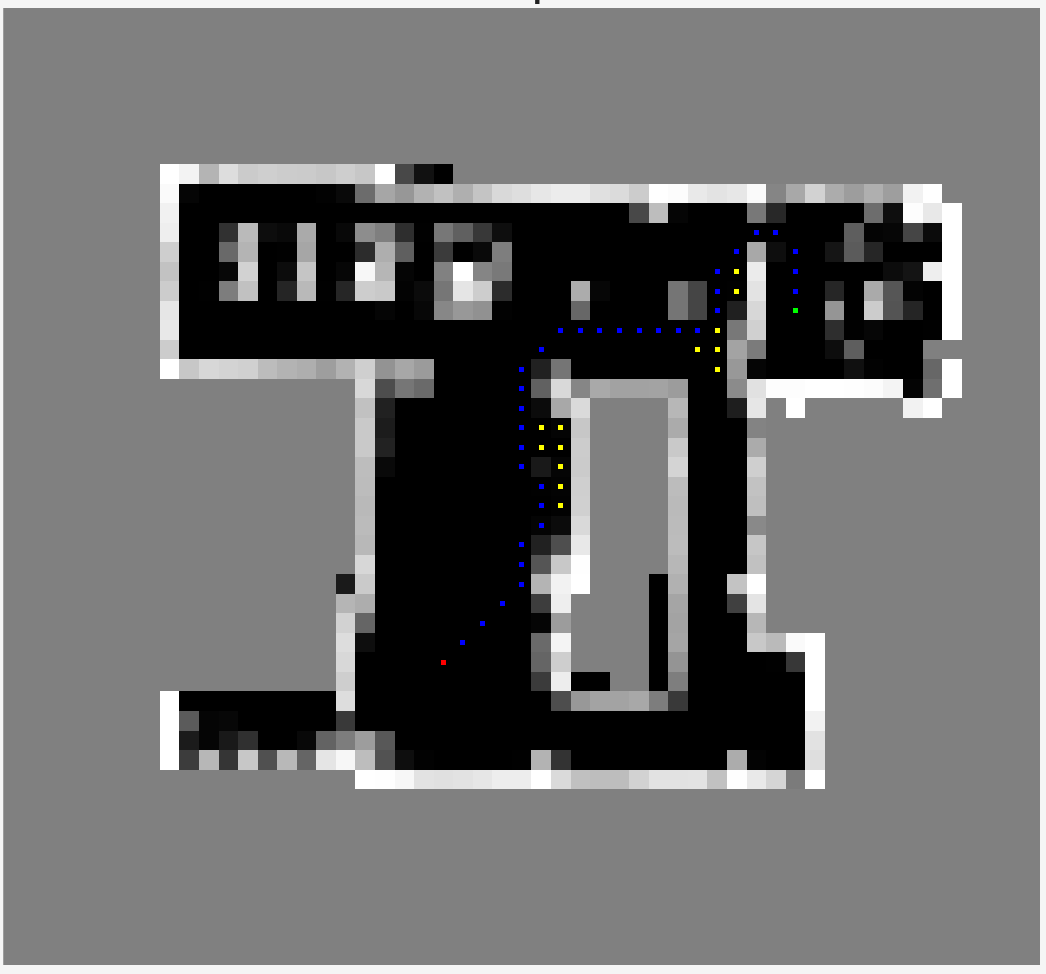

`planning_framework`

`done`

`path cost: `

`   41.5080`

`path length: `

`   38.9706`

`number of nodes visited: `

`    48`

Y finalmente, para k = 10:

 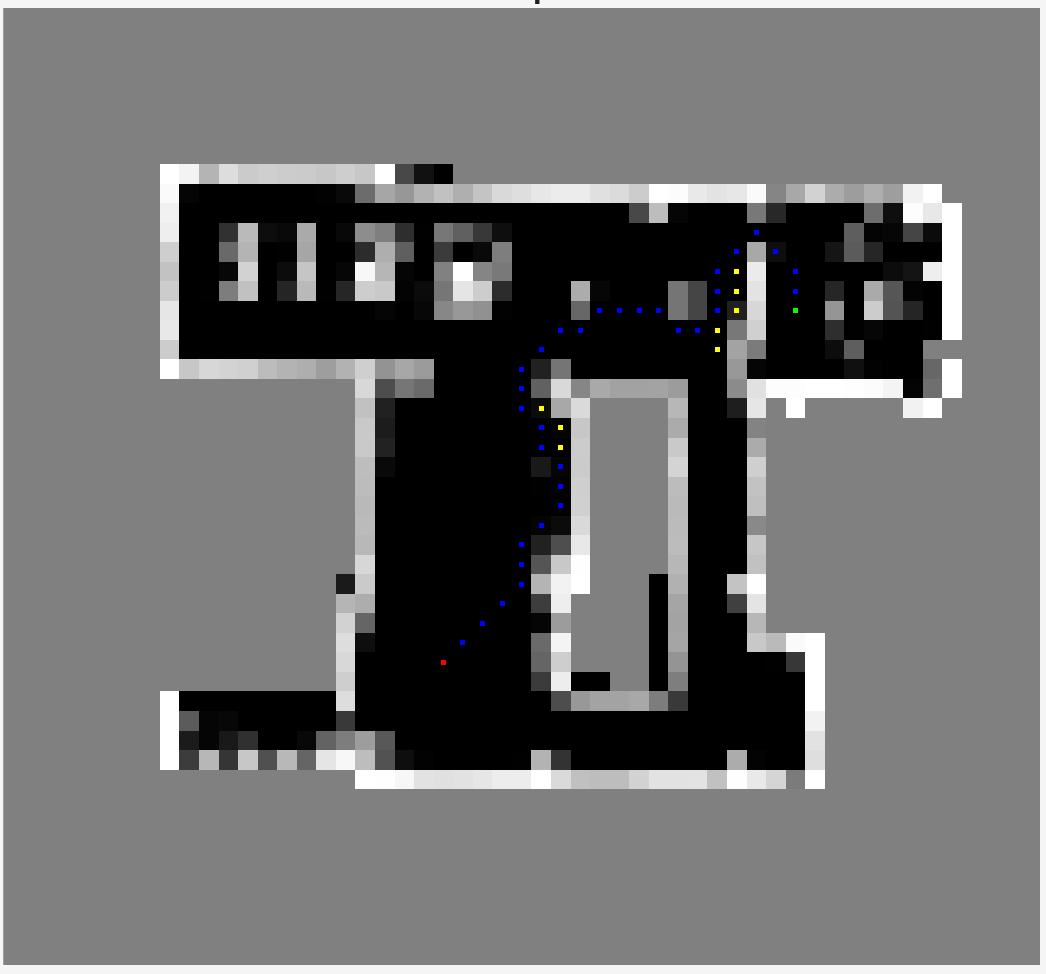

`planning_framework`

`done`

`path cost: `

`   52.8687`

`path length: `

`   40.0416`

`number of nodes visited: `

`    42`

`solo se recorren 6 nodos menos y el costo aumenta 11.3607.`